# **ADCIRC in MATLAB**

## Setup

See Demo1_GettingStartedWithAdcircInMatlab.mlx

## Open a time-dependent netCDF ADCIRC file

In this part of the demo, we'll examine several time-dependent ADCIRC files, starting with the fort.63.nc file.  

urlbase='http://tds.renci.org:8080/thredds/dodsC/tc/florence/00/nc_inundation_v9.99_w_rivers/pod.penguincomputing.com/OwiHindcast/hindcast/';
ncfile='fort.63.nc'

ncfile = 'fort.63.nc'

nc=ncgeodataset([urlbase '/' ncfile]);
nc.variables

ans = 17×1 cell array
    {'element'    }
    {'adcirc_mesh'}
    {'neta'       }
    {'nvdll'      }
    {'max_nvdll'  }
    {'ibtypee'    }
    {'nbdv'       }
    {'nvel'       }
    {'nvell'      }
    {'max_nvell'  }
    {'ibtype'     }
    {'nbvv'       }
    {'zeta'       }
    {'time'       }
    {'x'          }
    {'y'          }
    {'depth'      }

Note that the grid variables (e,x,y,depth, etc) are in this file as well.  The variable we are interested in is the `zeta` variable. 

We will retrieve the variable **object**, but not the entire dataset.  We'll call the MATLAB variable zeta.

zeta=nc{'zeta'}

zeta =   264×624782 ncgeovariable array with properties:

       dataset: [1×1 ncgeodataset]
          name: 'zeta'
          axes: {3×1 cell}
    attributes: {8×2 cell}

Note that `zeta` (the MATLAB variable, not the netCDF variable of the same name) is an nctoolbox/ncgeovariable object of size 264x624782.  The row is time, the column is ADCIRC nodes.  So there are 264 timesteps in this ADCIRC output file.

Let's also get out the `time` variable.  

time=nc.time('time');
ntimes=size(time,1)

ntimes =    264

`time` now contains the model output times in MATLAB's datenum format. Examine the first time:

time(1)

ans =      7.373100416666666e+05

datestr(time(1))

ans = '07-Sep-2018 01:00:00'

We can convert this to MATLAB's datetime, which is useful for plotting later on.  We'll call it dttime for "datetime time".

dttime=datetime(datevec(time));
dttime(1)

ans = datetime
   07-Sep-2018 01:00:00

## Extract the Grid

If we don't already have the ADCIRC grid, get it the same as previous. 

TheGrid=ExtractGrid(nc);

TheGrid = struct with fields:
              name: 'nc_inundation_v9.99_w_rivers'
                 e: [1234231×3 double]
                 x: [624782×1 double]
                 y: [624782×1 double]
                 z: [624782×1 double]
               bnd: [15627×2 double]
           ar_cart: [1234231×1 double]
            A_cart: [1234231×3 double]
           A0_cart: [1234231×2 double]
            B_cart: [1234231×3 double]
            T_cart: [1234231×3 double]
           dx_cart: [1234231×3 double]
           dy_cart: [1234231×3 double]
           dl_cart: [1234231×1 double]
    interiorangles: [1234231×3 double]
             acute: [1234231×1 logical]
                ar: [1234231×1 double]
              ineg: [0×1 double]
                EL: [1234231×3 double]
                dl: [1234231×1 double]
           triQual: [1234231×1 double]
                 A: [1234231×3 double]
                 B: [1234231×3 double]
                A0: [1234231×2 double]
                 T: [1234231×3 d

## Loop over the time dimension and interpolate 

One way to handle time is just to loop over the time variable.  In some cases, this is the easiest  approach.  In side the loop, we'll interpolate to the location previously used.

lon=-76.5;
lat=35.0;
j=findelem(TheGrid,[lon lat]); 

Pre-allocate space for the array that will hold the interpolated values. For a small 1-d array, this is not critical, but for larger, multidimensional arrays, it is MUCH more efficient to pre-allocate.

z_i=nan([ntimes 1]);

Here's the loop.  This still takes a bit of time, because each time slice is fetched from the data file, which in this case is the THREDDS server.  We'll examine other ways of getting smaller chunks of the data later in a different demo.

for it=1:ntimes
    %get the zeta field for this time
    ThisZeta=zeta(it,:)';
    z_i(it)=interp_scalar(TheGrid,ThisZeta,lon,lat,j);
end

Make a plot of the water level at this location.

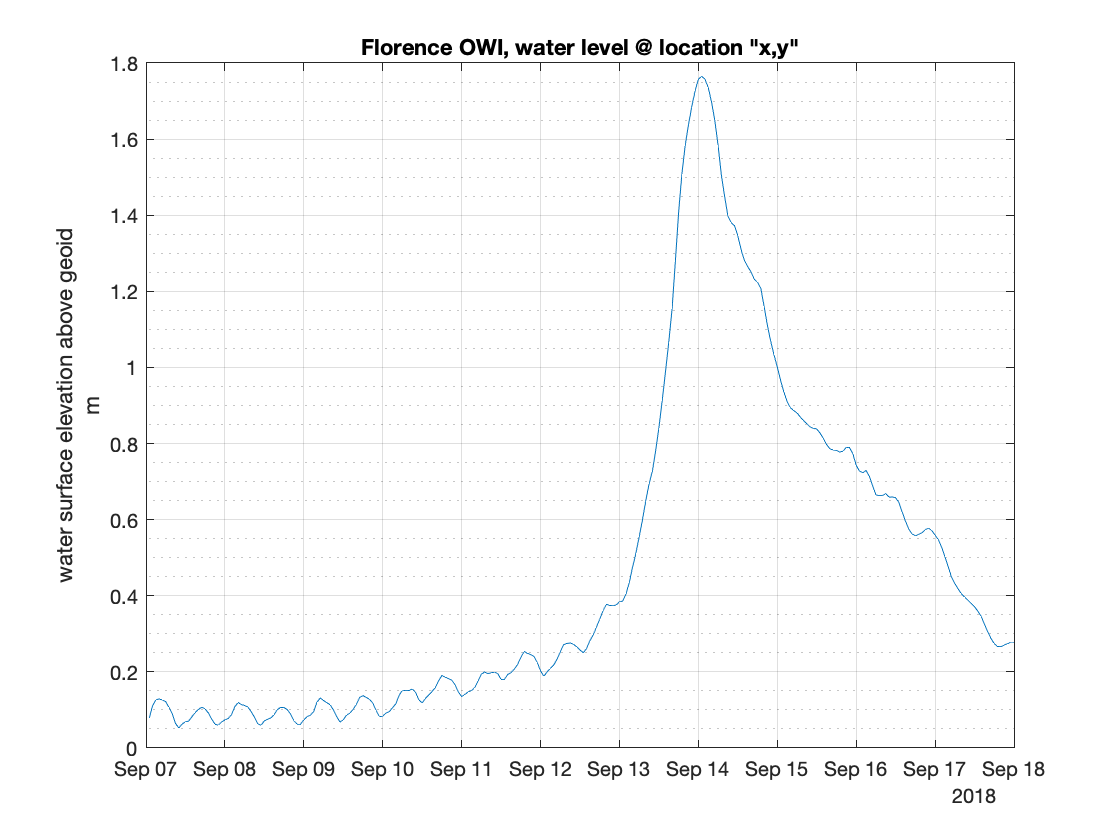

plot(dttime,z_i)
ylabel({zeta.attribute('long_name'),zeta.attribute('units')})
title('Florence OWI, water level @ location "x,y"')
grid on
grid minor

Now, let's get the wind velocity from the fort.74.nc file.  Fewer comments, since the process is exactly the same as above. Remember that this is ADCIRC's version of the OWI winds, accounting for overland friction and canopy.  This is not the OWI winds directly.  We'll look at that in Demo4 (TBW).

ncfile='fort.74.nc';
nc74=ncgeodataset([urlbase '/' ncfile]);
% note the variables windx and windy
nc74.variables

ans = 18×1 cell array
    {'element'    }
    {'adcirc_mesh'}
    {'neta'       }
    {'nvdll'      }
    {'max_nvdll'  }
    {'ibtypee'    }
    {'nbdv'       }
    {'nvel'       }
    {'nvell'      }
    {'max_nvell'  }
    {'ibtype'     }
    {'nbvv'       }
    {'windy'      }
    {'time'       }
    {'x'          }
    {'y'          }
    {'depth'      }
    {'windx'      }

windx=nc74{'windx'};
windy=nc74{'windy'};
windx_name=windx.attribute('long_name');
windy_name=windy.attribute('long_name');
units=windx.attribute('units');

units = 'm s-1'

% again, we pre-allocate
windx_i=nan([ntimes 1]);
windy_i=nan([ntimes 1]);

for it=1:ntimes
    %get the windx,y field for this time
    ThisWindX=windx(it,:)';
    ThisWindY=windy(it,:)';
    windx_i(it)=interp_scalar(TheGrid,ThisWindX,lon,lat,j);
    windy_i(it)=interp_scalar(TheGrid,ThisWindY,lon,lat,j);
end

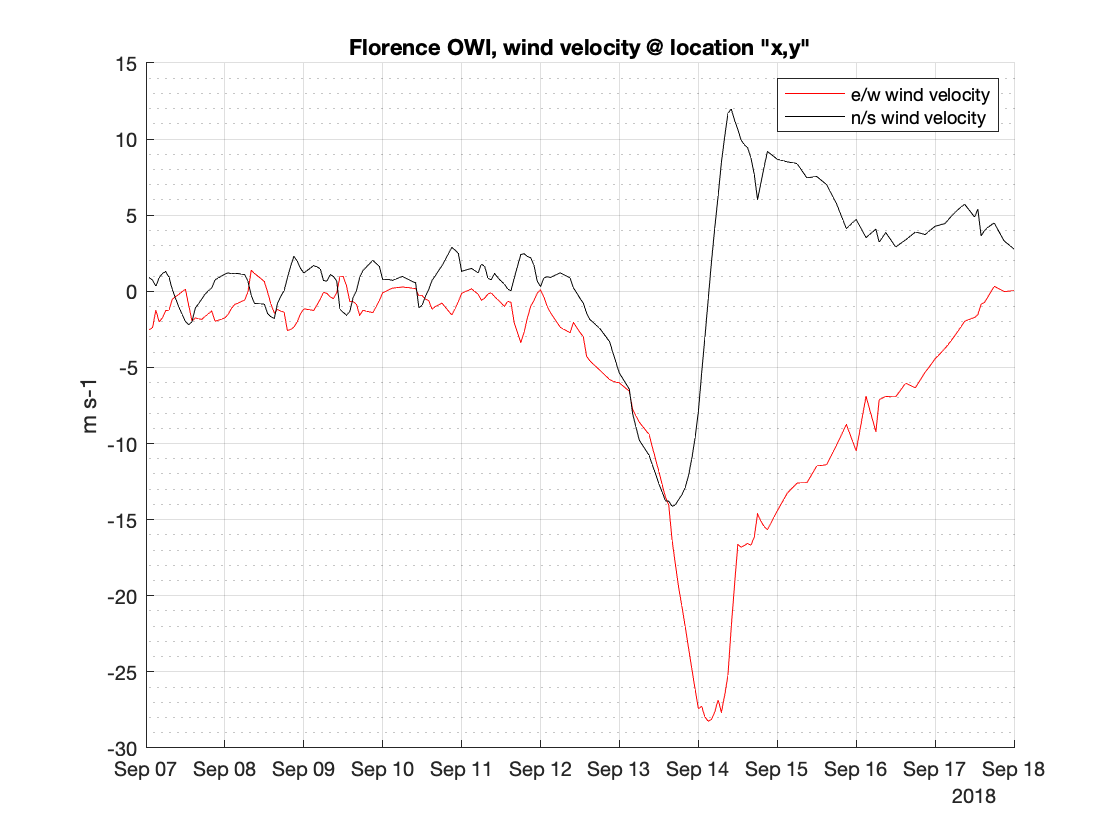

figure
line(dttime,windx_i,'DisplayName',windx_name,'Color','r')
line(dttime,windy_i,'DisplayName',windy_name,'Color','k')
ylabel(units)
title('Florence OWI, wind velocity @ location "x,y"')
legend
grid on
grid minor